# Project: Find Optimal Buying-low Selling-high Strategy for mean-reverting stock

## Yida Chen

## Simulate the Stock Price with Brownian Motion:

The stock price is $S\left(t\right)\;=e^{X\left(t\right)}$ where $X\left(t\right)$ is governed by the differential equation below:


$$\textrm{dX}\left(t\right)=\lambda \left(\mu -X\left(t\right)\right)\textrm{dt}+\sigma \;\textrm{dW}\left(t\right)$$


$\lambda$ = Speed of mean reversion

$\mu$ = Long run mean

$\sigma$ = Volatility of the process

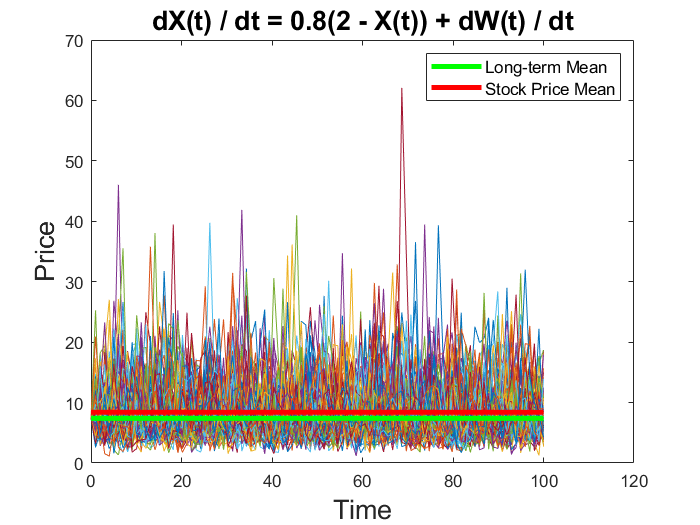

clf;
clear;

NSample = 100;
N_T = 100;
T = 100;
t0=0;

[TProcess, BProcess] = BrownMotion(NSample, t0, 0, T, N_T);

t0=0;
y0 = [2];
h = (T - t0) / (N_T - 1);


stock_prices = [];

for k=1:NSample
    w_diff = diff(BProcess(:, k));
%     w_diff = normrnd(0, sqrt(h), N_T-1);
    x_prime = @(t, y) 0.8 * (2 - y(1)) + 0.5 * (w_diff(int32(t / h) + 1));
    f = {x_prime};
    
    [ymat, t] = EulerSystem(f, t0, y0, T, N_T);
    stock_prices = cat(2, stock_prices, exp(ymat(:, 1)));
end

clf;
for k=1:NSample
    plot(t, stock_prices(:, k))
    hold on
end
p = [];
p(1) = plot(t, ones(length(t), 1) * exp(2),'g','LineWidth',3, 'DisplayName', "Long-term Mean");
p(2) = plot(t, ones(length(t), 1) * mean(mean(stock_prices)),'r','LineWidth',3, 'DisplayName', "Stock Price Mean");
title("dX(t) / dt = 0.8(2 - X(t)) + dW(t) / dt",'FontSize', 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
legend(p, 'FontSize', 10)
hold off

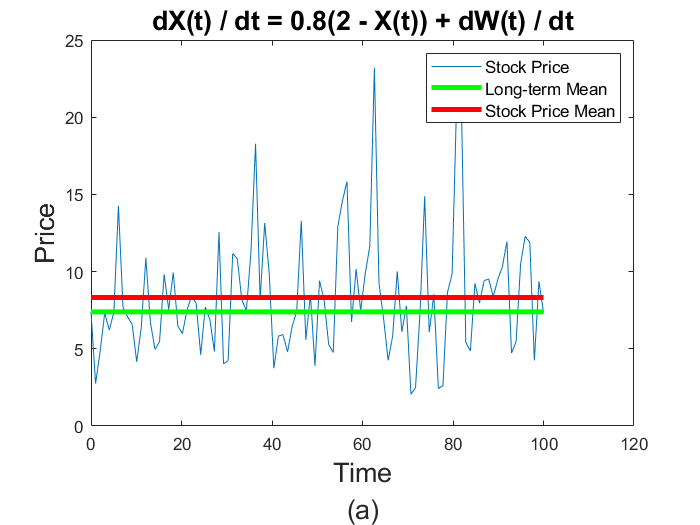

clf;
plot(t, stock_prices(:, 2))
hold on
plot(t, ones(length(t), 1) * exp(2),'g','LineWidth',3)
plot(t, ones(length(t), 1) * mean(stock_prices(:, 2)),'r','LineWidth',3)
hold off
title("dX(t) / dt = 0.8(2 - X(t)) + dW(t) / dt",'FontSize', 16)
xlabel({"Time", "(a)"}, 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
legend("Stock Price", "Long-term Mean", "Stock Price Mean",'FontSize', 10)

## Global Optimization

Calculate the reward over multiple possible trends of stock prices given the same initial conditions.

b0 = 5

b0 = 5

s0 = 18

s0 = 18

reward =     8.5539    8.8866    8.6791    8.8907    8.9217    8.9359    8.7748    8.9187    8.8243    8.8702    8.8359    8.8983    8.8412    8.8535    8.8085    8.8950    8.7884    8.8914    8.8245    8.8657    8.8286    8.9291    8.8329    8.8646    8.8183    8.8490    8.7945    8.8619    8.8434    8.9508    8.8573    8.9286    8.8026    8.9562    8.8184    8.9194    8.8779    8.8349    8.8815    8.8973    8.8809    8.9510    8.8060    9.0121    8.8373    8.9420    8.8599    8.9853    8.8471    8.9786


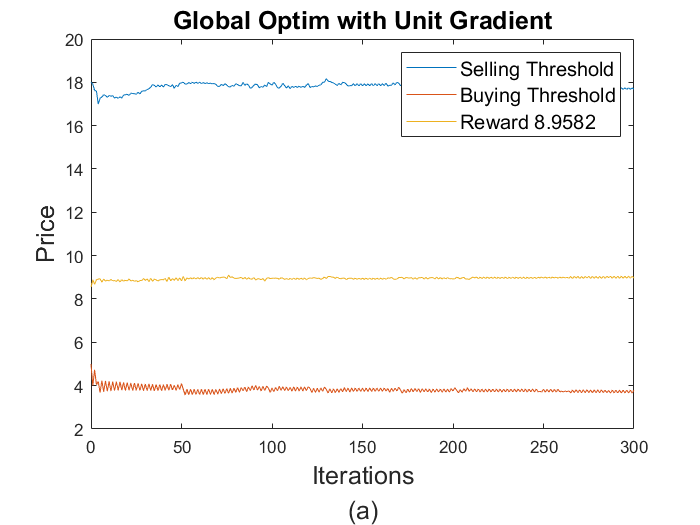

reward =     8.5539    8.9153    8.6159    8.8423    8.6785    8.8736    8.7755    8.8715    8.8377    8.9071    8.8304    8.9308    8.9732    8.9496    8.9449    8.9363    8.9317    8.9497    8.9716    8.9615    8.9615    8.9739    8.9529    8.9828    8.9453    8.9623    9.0382    8.9631    9.0793    8.9639    9.0787    8.8842    9.0735    8.8893    9.0674    8.8904    9.0630    8.9533    8.9787    8.9574    9.1016    8.8843    9.0980    8.8879    9.0946    8.8913    9.0914    8.8339    9.0883    8.8369


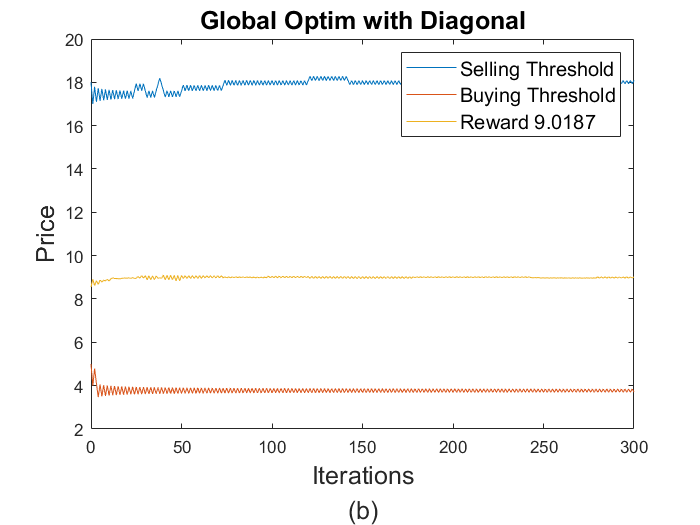

reward =     8.5539    8.9421    8.6425    8.8502    8.7636    8.7493    8.8043    8.7804    8.8189    8.8660    8.8209    8.8438    8.8365    8.8839    8.8458    8.8758    8.8536    9.0023    8.8602    8.9964    8.8659    8.9900    8.8740    8.9855    8.8784    9.0168    8.8828    9.0132    8.8864    9.0098    8.8904    9.0008    8.8934    8.9980    8.8988    8.9955    8.9014    8.9931    8.9021    8.9909    8.8765    8.9888    8.8785    8.9868    8.8805    8.9801    8.8823    8.9783    8.8840    8.9767


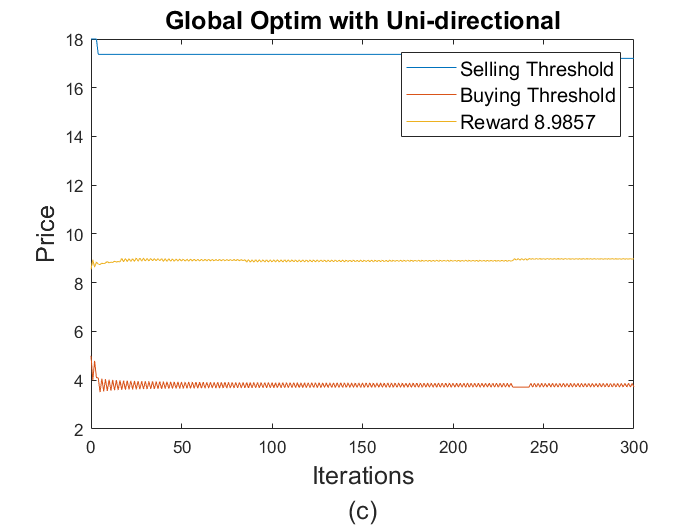

num_iter = 300;

rewards = {};
s_s = {};
b_s = {};
strategis = ["Adaptive Gradient", "Unit Gradient", "Diagonal", "Uni-directional"];
x_labels = ["0", "(a)", "(b)", "(c)"];

for mode=1:3
    s = [];
    b = [];
    reward = [];
    b(1) = b0;
    s(1) = s0;
    for iter=1:num_iter    
        c = (iter) ^ (-1/3);
        reward(iter) = TransactionReward(stock_prices, b(iter), s(iter), T);
        
        incre_b = b(iter) + c;
        reward_incre_b = TransactionReward(stock_prices, incre_b, s(iter), T);
        
        decre_b = b(iter) - c;
        reward_decre_b = TransactionReward(stock_prices, decre_b, s(iter), T);
        
        incre_s = s(iter) + c;
        reward_incre_s = TransactionReward(stock_prices, b(iter), incre_s, T);
        
        decre_s = s(iter) - c;
        reward_decre_s = TransactionReward(stock_prices, b(iter), decre_s, T);
        
        gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
        gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
        
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        [next_b, next_s] = update_bs(b(iter), s(iter), ...
            gradient_b, gradient_s, ...
            iter, c, mode);
        
        b(iter + 1) = next_b;
        s(iter + 1) = next_s;
        
        change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
        if iter > 1 && change < 0.001
            break
        end
    end
    reward(iter + 1) = TransactionReward(stock_prices, b(iter + 1), s(iter + 1), T)
    
    figure()
    plot(linspace(0, length(reward) - 1, length(reward)), s)
    hold on
    plot(linspace(0, length(reward) - 1, length(reward)), b)
    plot(linspace(0, length(reward) - 1, length(reward)), reward)
    legend("Selling Threshold", "Buying Threshold", "Reward" + " " + string(reward(end)), "FontSize", 12)
    title("Global Optim with " + strategis(mode + 1), "FontSize", 15)
    hold off
    rewards{mode + 1} = reward;
    s_s{mode + 1} = s;
    b_s{mode + 1} = b;
    ylabel("Price", "FontSize", 15)
    xlabel({"Iterations", x_labels(mode + 1)}, "FontSize", 15)
end

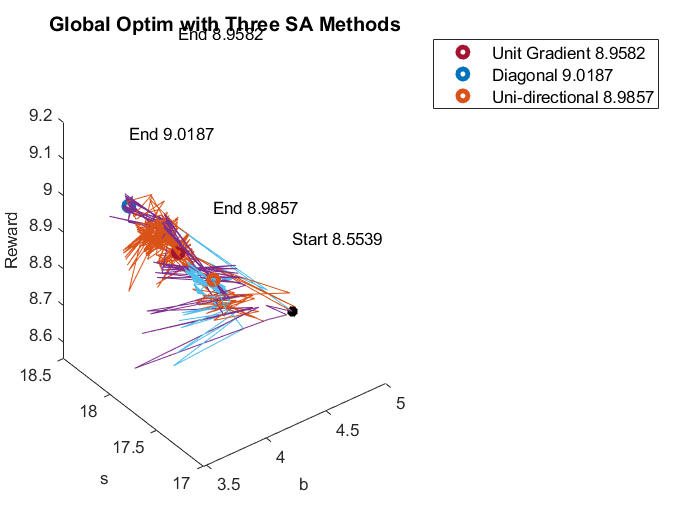

clf;
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    plot3(b(1), s(1), reward(1), "*black", "linewidth", 3)
    hold on
    plot3(b, s, reward)
    hold on
    if i == 2
       text(b(end), s(end), reward(end) + 0.6, append('End ', string(reward(end)))) 
    else
       text(b(end), s(end), reward(end) + 0.2, append('End ', string(reward(end)))) 
    end
end
text(b_s{i}(1), s_s{i}(1), rewards{i}(1) + 0.2, append('Start ', string(rewards{i}(1))))

p = [];
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    p(i-1) = plot3(b(end), s(end), reward(end), "o", "linewidth", 3, 'DisplayName', strategis(i) + " " + string(reward(end)));
end

xlabel("b", "FontSize", 10)
ylabel("s", "FontSize", 10)
zlabel("Reward", "FontSize", 10)
title("Global Optim with Three SA Methods", "FontSize", 12)

legend(p, "FontSize", 10)

## Before Optimizing:

What we gain by using the initial buying and selling threshold to perform one transaction on one of the stocks.

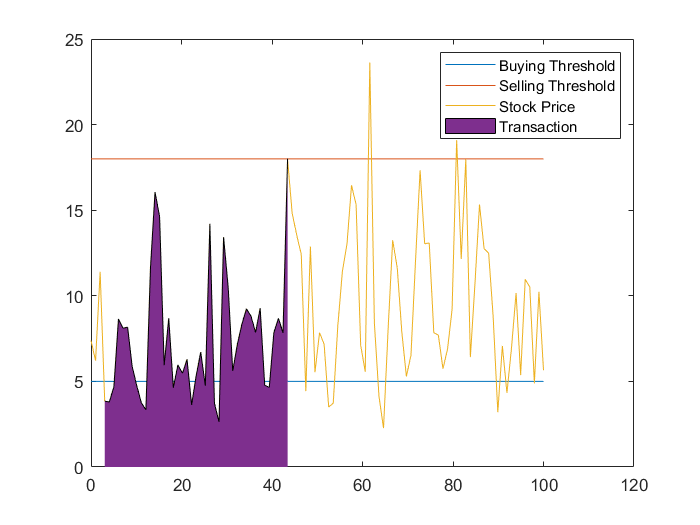

[tau_b,ColNrs] = find(stock_prices(:, 1) < b0);
[tau_s,ColNrs] = find(stock_prices(:, 1) > s0);
[tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));

clf;
plot(t, ones(length(t), 1) * b0)
hold on
plot(t, ones(length(t), 1) * s0)
plot(t, stock_prices(:, 1))

one_buy_time = tau_b(1);
one_sell_time = tau_s(1);
ix = [one_buy_time: 1: one_sell_time] / (N_T - 1) * T - 1;
yz = stock_prices(one_buy_time:one_sell_time, 1);
area(ix, yz)

legend("Buying Threshold", "Selling Threshold", "Stock Price", "Transaction")

disp("Total revenue before Optimization")

Total revenue before Optimization


phi = exp(-0.01 * tau_s(1) / length(stock_prices(:, 1)) * T) * s0 * (1 - 0.01) - exp(-0.01 * tau_b(1) / length(stock_prices(:, 1)) * T) * b0 * (1 + 0.01)

phi = 6.6247

## After Optimization:

What we gain using the optimized buying and selling threshold to perform one transaction on the same stock

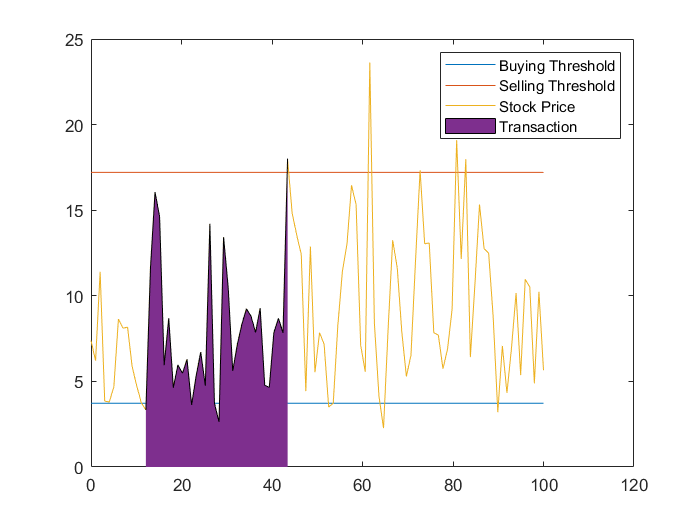

[tau_b,ColNrs] = find(stock_prices(:, 1) < b(end));
[tau_s,ColNrs] = find(stock_prices(:, 1) > s(end));
[tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));

clf;
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, stock_prices(:, 1))

one_buy_time = tau_b(1);
one_sell_time = tau_s(1);
ix = [one_buy_time: 1: one_sell_time] / (N_T - 1) * T - 1;
yz = stock_prices(one_buy_time:one_sell_time, 1);
area(ix, yz)

legend("Buying Threshold", "Selling Threshold", "Stock Price", "Transaction")

disp("Total revenue after Optimization");

Total revenue after Optimization


phi = exp(-0.01 * tau_s(1) / length(stock_prices(:, 1)) * T) * s(end) * (1 - 0.01) - exp(-0.01 * tau_b(1) / length(stock_prices(:, 1)) * T) * b(end) * (1 + 0.01)

phi = 7.6695

## Local Optimization

Use only one OU functions, but buy and sell multiple times in one period.

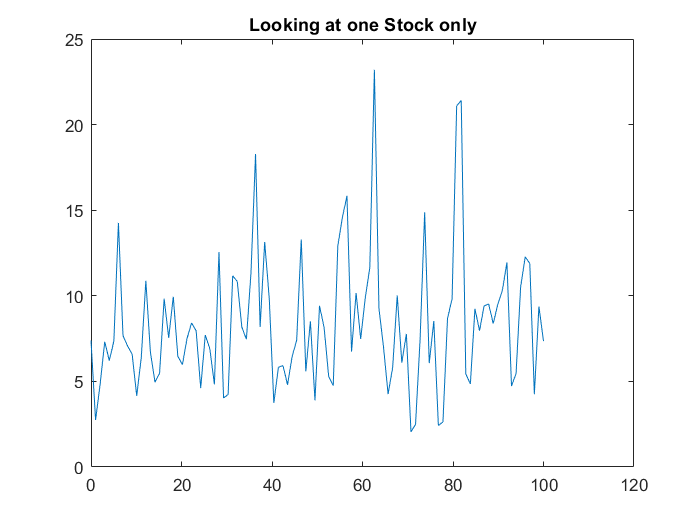

b0 = 5;
s0 = 18;
num_iter = 300;

% stock_price = stock_prices(:, randi(NSample));
stock_price = stock_prices(:, 2);

clf;
plot(t, stock_price)
title("Looking at one Stock only")
hold off

reward =    19.0419   19.1205   18.3187   20.0492   19.5407   20.7537   20.0668   21.0950   20.1821   21.0924   20.5114   21.3371   20.5854   21.3462   20.6690   21.3576   20.8727   20.5533   21.1819   20.7301   21.3476   20.7935   21.3621   20.9653   20.6701   21.2035   20.8070   21.3413   21.0645   21.5597   21.2070   21.6860   21.2358   21.7001   21.2633   20.9348   21.3792   21.1334   21.5661   21.2531   21.6747   21.2768   21.6883   21.2996   21.0038   21.4013   21.7946   21.4226   21.1384   21.5194


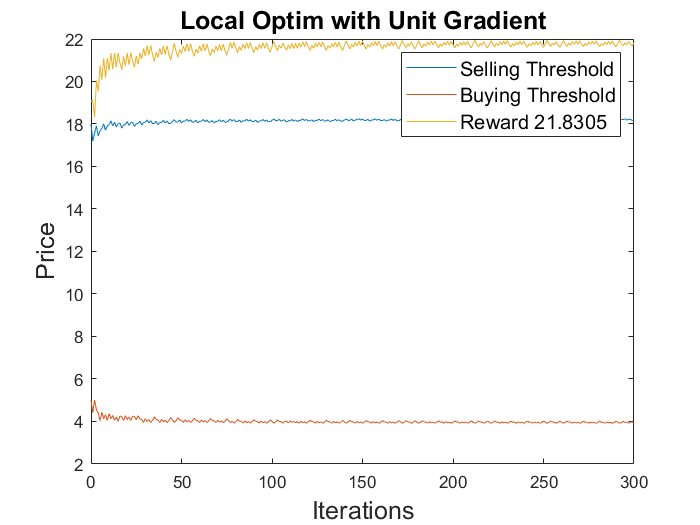

reward =    19.0419   19.6987   19.3624   19.6412   19.3970   21.0950   19.5431   20.9816   19.6347   20.9058   21.0458   20.9124   21.0402   20.9174   21.9184   20.9513   21.8877   20.9793   21.8621   21.0028   21.8404   21.0230   21.8216   21.0406   21.8051   21.0560   21.7906   21.0697   21.7776   21.0820   21.7659   21.0932   21.7553   21.1033   21.7457   21.1125   21.7368   21.1210   21.7287   21.1289   21.7211   21.1361   21.7141   21.1429   21.7076   21.1492   21.7015   21.1551   21.6957   21.1606


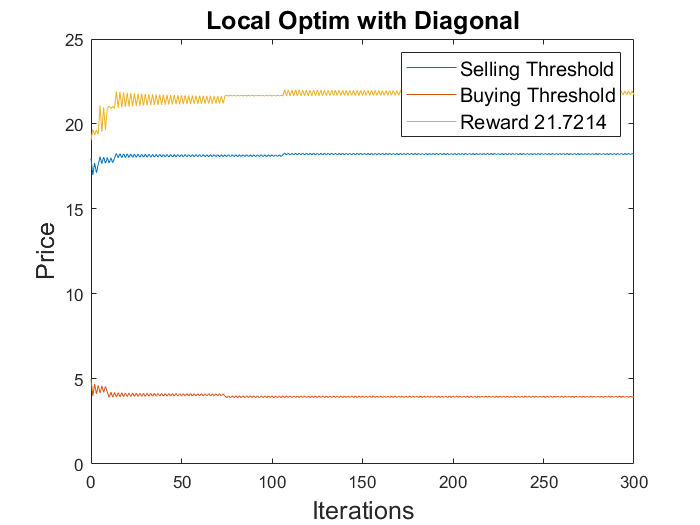

reward =    19.0419   17.3903   19.0641   17.6676   18.9017   19.8599   18.9835   19.7964   19.0347   19.7541   19.0707   19.7233   19.0976   19.6996   19.1188   19.6806   19.1360   19.6650   19.1713   19.6518   19.1835   19.6405   19.1940   19.6307   19.2032   19.6221   19.2113   19.6144   19.2186   19.6075   19.2251   19.6013   19.2311   19.5956   19.2365   19.5905   19.2414   19.5857   19.2460   19.5813   19.9124   19.5854   19.9085   19.5892   19.9049   19.5927   19.9015   19.5960   19.8983   19.5991


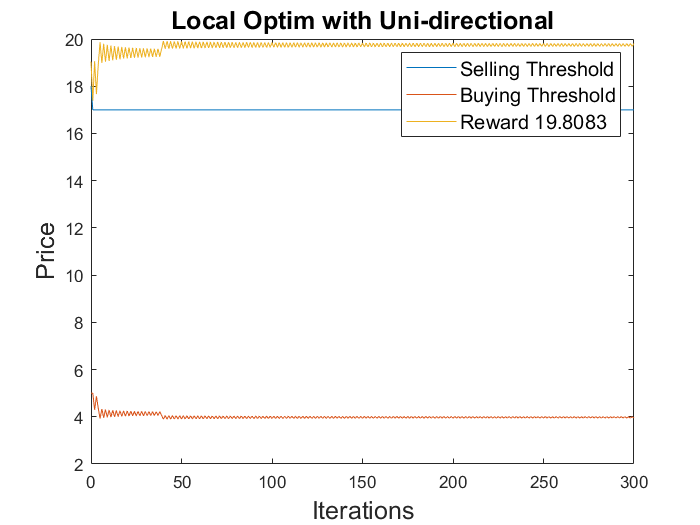


rewards = {};
s_s = {};
b_s = {};
strategis = ["Adaptive Gradient", "Unit Gradient", "Diagonal", "Uni-directional"];

for mode=1:3
    s = [];
    b = [];
    reward = [];
    b(1) = b0;
    s(1) = s0;
    for iter=1:num_iter
        c = (iter) ^ (-1/2);
        reward(iter) = MultiTransactionReward(stock_price, b(iter), s(iter), T);
        
        incre_b = b(iter) + c;
        reward_incre_b = MultiTransactionReward(stock_price, incre_b, s(iter), T);
        
        decre_b = b(iter) - c;
        reward_decre_b = MultiTransactionReward(stock_price, decre_b, s(iter), T);
        
        incre_s = s(iter) + c;
        reward_incre_s = MultiTransactionReward(stock_price, b(iter), incre_s, T);
        
        decre_s = s(iter) - c;
        reward_decre_s = MultiTransactionReward(stock_price, b(iter), decre_s, T);
        
        gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
        gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
        
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        [next_b, next_s] = update_bs(b(iter), s(iter), ...
            gradient_b, gradient_s, ...
            iter, c, mode);
        
        b(iter + 1) = next_b;
        s(iter + 1) = next_s;
        
        change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
        if iter > 1 && change < 0.001
            break
        end
    end
    
    reward(iter + 1) = MultiTransactionReward(stock_price, b(iter + 1), s(iter + 1), T)
    
    figure()
    plot(linspace(0, length(reward) - 1, length(reward)), s)
    hold on
    plot(linspace(0, length(reward) - 1, length(reward)), b)
    plot(linspace(0, length(reward) - 1, length(reward)), reward)
    legend("Selling Threshold", "Buying Threshold", "Reward" + " " + string(reward(end)), "FontSize", 12)
    title("Local Optim with " + strategis(mode + 1), "FontSize", 15)
    hold off
    rewards{mode + 1} = reward;
    s_s{mode + 1} = s;
    b_s{mode + 1} = b;
    ylabel("Price", "FontSize", 15)
    xlabel("Iterations", "FontSize", 15) 
end

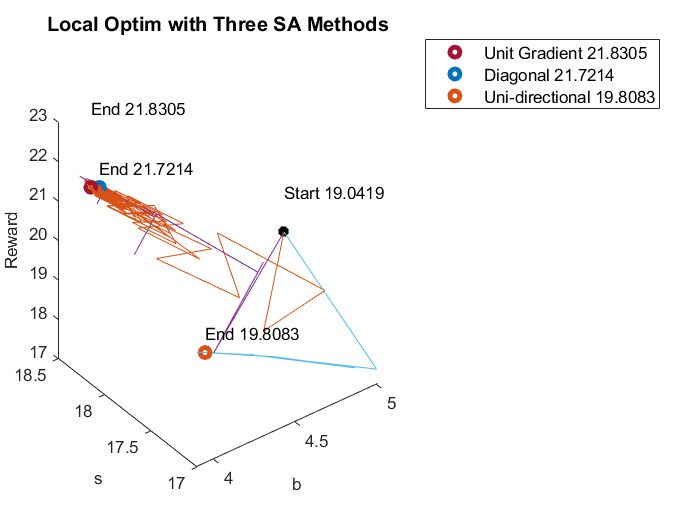

clf;
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    plot3(b(1), s(1), reward(1), "*black", "linewidth", 3)
    hold on
    plot3(b, s, reward)
    hold on
    if i == 2
       text(b(end), s(end), reward(end) + 2, append('End ', string(reward(end)))) 
    else
       text(b(end), s(end), reward(end) + 0.5, append('End ', string(reward(end)))) 
    end
end
text(b_s{i}(1), s_s{i}(1), rewards{i}(1) + 1, append('Start ', string(rewards{i}(1))))

p = [];
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    p(i-1) = plot3(b(end), s(end), reward(end), "o", "linewidth", 3, 'DisplayName', strategis(i) + " " + string(reward(end)));
end

xlabel("b", "FontSize", 10)
ylabel("s", "FontSize", 10)
zlabel("Reward", "FontSize", 10)
title("Local Optim with Three SA Methods", "FontSize", 12)

legend(p, "FontSize", 10)

b(end), s(end), reward(end)

ans = 3.9476

ans = 17

ans = 19.8083

## Using the inital Buying and Selling Thresholds:

Much less gross income from all transactions.

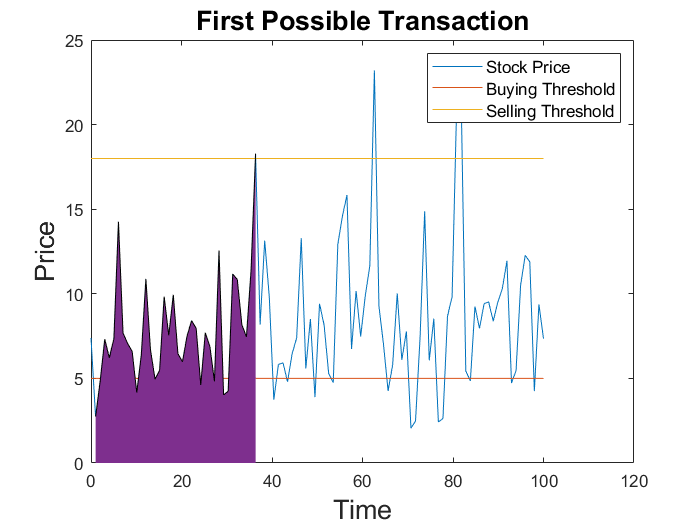

one_stock_price = stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b0 and s0

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b0, s0); 

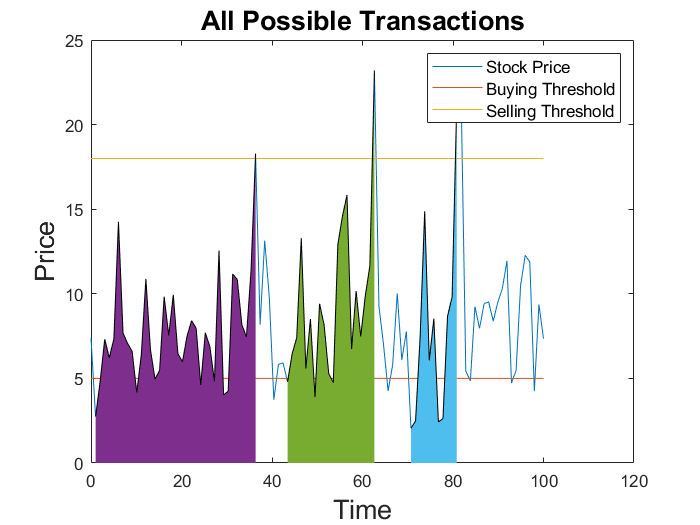

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, one_stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)


for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / (N_T - 1) * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Stock Price", "Buying Threshold", "Selling Threshold", "FontSize", 10)
title("All Possible Transactions", "FontSize", 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

## Compute Revenue using the initial Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s0 * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b0 * (1 + 0.01)

phi =     7.3589    6.2384    5.4446


disp("Total revenue before Optimization")

Total revenue before Optimization


phi = sum(phi)

phi = 19.0419

## Using the optimized Buying and Selling Thresholds:

We get a better sum of revenues from all transactions we made.

one_stock_price = stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b and s

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b(end), s(end)); 

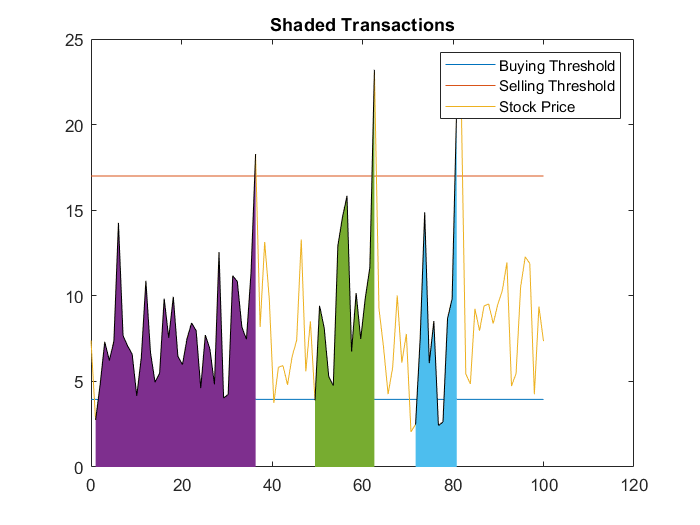

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / (N_T - 1) * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Buying Threshold", "Selling Threshold", "Stock Price")
title("Shaded Transactions")
hold off

## Compute Revenue using the Optimized Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s(end) * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b(end) * (1 + 0.01)

phi =     7.7169    6.5452    5.5462


disp("Total revenue after Optimization")

Total revenue after Optimization


phi = sum(phi)

phi = 19.8083

## Explore the reward function on all possible '`b'` and 's':

% Explore the surface of the reward function at all possible b and s
% b and s are the x and y axes of the plot
% and the surface (z) is the reward computed at a given (b, s)
s_all = linspace(3, 23, 50);
b_all = linspace(3, 23, 50);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = MultiTransactionReward(stock_price, b_all(i), s_all(j), T);
    end
end

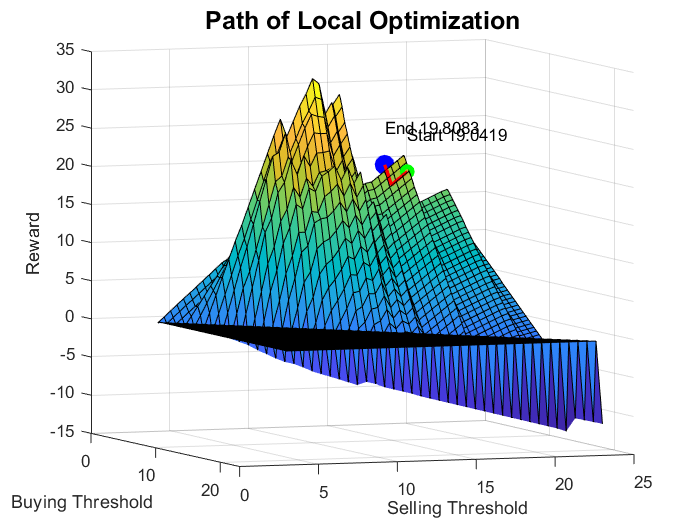

clf;
surf(b_all, s_all, reward_all)
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
%zlim([-50, 50])
hold on

plot3(b(1), s(1), reward(1), 'ogreen','linewidth',3)
plot3(b, s, reward, 'red','linewidth',2)
plot3(b(end), s(end), reward(end), 'oblue','linewidth',6)
text(b(1), s(1), reward(1) + 5, append('Start ', string(reward(1))))
text(b(end), s(end), reward(end) + 5, append('End ', string(reward(end))))
title("Path of Local Optimization", "FontSize", 15)
hold off

## Interactive Plot:

that shows how our algorithm are finding the local maximum of that reward function

s_all = linspace(3, 23, 500);
b_all = linspace(3, 23, 500);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = MultiTransactionReward(stock_price, b_all(i), s_all(j), T);
    end
end

Interactive plot. Go to the next optimal point by pressing the key "k" on the keyboard.

clf;
h = surf(b_all, s_all, reward_all);
set(h,'LineStyle','none')
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
hold on

plot3(b(1), s(1), reward(1), 'ogreen','linewidth',3)
step = 5;
for i=1:step:length(s)-1
    key_press = waitforbuttonpress;
    val = get(gcf, "CurrentCharacter");
    while val ~= "k"
        key_press = waitforbuttonpress;
        val = get(gcf, "CurrentCharacter");
    end
    if i ~= 1
        delete(h);
    end
    plot3(b(i:i+ step -1), s(i:i+ step -1), reward(i:i+ step -1), 'red','linewidth',2)
    h = plot3(b(i+step -1), s(i+ step -1), reward(i+ step -1), 'oblue','linewidth',3);
    hold on
end

Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted

delete(h)
plot3(b(end), s(end), reward(end), 'oblue','linewidth',6)
hold off

key_press = waitforbuttonpress
val = get(gcf, "CurrentCharacter")

# Function Definitions:

function [ymat, t]=EulerSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / (N - 1);
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N
        for i=1:length(y0)
            ymat(j, i) = ymat(j - 1,i) + h * f{i}(t(j-1), ymat(j - 1, :));
            t(j) = t(j - 1) + h;
        end
    end
end

function [ymat, t]=RKSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / N;
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N + 1
        for i=1:length(y0)
            k1 = h * f{i}(t(j-1), ymat(j - 1, :));
            k2 = h * f{i}(t(j-1) + h, ymat(j - 1, :) + k1);
            ymat(j, i) = ymat(j - 1,i) + (1 / 2) * (k1 + k2);
            t(j) = t(j - 1) + h;
        end
    end
end

function [TProcess, BProcess]=BrownMotion(sample, t0, y0, b, N)
    BProcess = [];
    TProcess = [];
    NSample = sample;
    N_T = N;
    T = b;
    
    for k = 1:NSample
        B = y0;
        t = t0;
        BProcess(1,k)=B; TProcess(1,k)=t;
        for i=2:N_T
            dt =  T/N_T;
            t = t + dt;
            B = B + sqrt(dt)*randn(1); %increments in B are normally distibuted with variance dt
            BProcess(i,k) = B;
            TProcess(i,k) = t;
        end
    end
end


function [next_b, next_s] = update_bs(b, s, gradient_b, gradient_s, ...
    iter, c, mode)
    eps =0.000001;
    % Update strategy 0 gradient vector
    if mode == 0
        next_b = b + gradient_b / iter;
        next_s = s + gradient_s / iter;
    % Update strategy 1 unit vector
    elseif mode == 1
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        next_b = b + gradient_b / (mag + eps) * c;
        next_s = s + gradient_s / (mag + eps) * c;
    % Update strategy 2 move in diagonal 
    elseif mode == 2
        if gradient_b > 0
            next_b = b + c;
        else
            next_b = b - c;
        end
        
        if gradient_s > 0
            next_s = s + c;
        else
            next_s = s - c;
        end
    % Update strategy 3 move in largest gradient (eithr b or s)
    elseif mode == 3
        if abs(gradient_s) > abs(gradient_b)
            next_b = b;
            if gradient_s > 0
                next_s = s + c;
            else
                next_s = s - c;
            end
        else
            next_s = s;
            if gradient_b > 0
                next_b = b + c;
            else
                next_b = b - c;
            end
        end
    end
end


% Global Optimization
% Optimize on one transaction of multiple different stock prices
function reward=TransactionReward(stock_prices, b, s, T)
    if b > s
        reward = 0;
        return
    end
    phi = [];
    for k=1:length(stock_prices(1, :))
        [tau_b,ColNrs] = find(stock_prices(:, k) < b);
        [tau_s,ColNrs] = find(stock_prices(:, k) > s);
        if length(tau_b) < 1
            continue
        end
        [tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));
        if length(tau_s) < 1
            continue
        end
        tau_b = tau_b(1);
        phi(k) = exp(-0.01 * tau_s / length(stock_prices) * T) * s * (1 - 0.01) - exp(-0.01 * tau_b / length(stock_prices) * T) * b * (1 + 0.01);
    end
    
    if length(phi) < 1
        reward = 0;
    else
        reward = sum(phi) / length(stock_prices(1, :));
    end       
end


% Local Optimization
% Optimize on multiple transaction of one randomly chosen stock
function reward=MultiTransactionReward(one_stock_price, b, s, T)
    if b > s
        reward = 0;
        return
    end
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        RowNrs = [];
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    break
                end
                if prev_s > length(tau_s)
                    break
                end
                i = RowNrs(1);
                break
            end
        end
        if length(RowNrs) < 1 
            break
        end
        if prev_s > length(tau_s)
            break
        end
        i = i + 1;
    end
    
    tau_b = buy_times;
    tau_s = sell_times;
    
    if length(tau_b) < 1
        reward = 0;
    else
        phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b * (1 + 0.01);
        reward = sum(phi);
    end
end


function [buy_times, sell_times]=find_set_of_selling_buying_time(one_stock_price, b, s)
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    return
                end
                if prev_s > length(tau_s)
                    return
                end
                i = RowNrs(1);
                break
            end
        end
        i = i + 1;
    end
end